## Resonance scanning

Consider an oscillator BVP in which we change the natural frequency instead of the driving frequency.


$$u'' + \omega_0^2\, u = 1, \qquad u(0)=-3,\quad u(\pi)=1$$


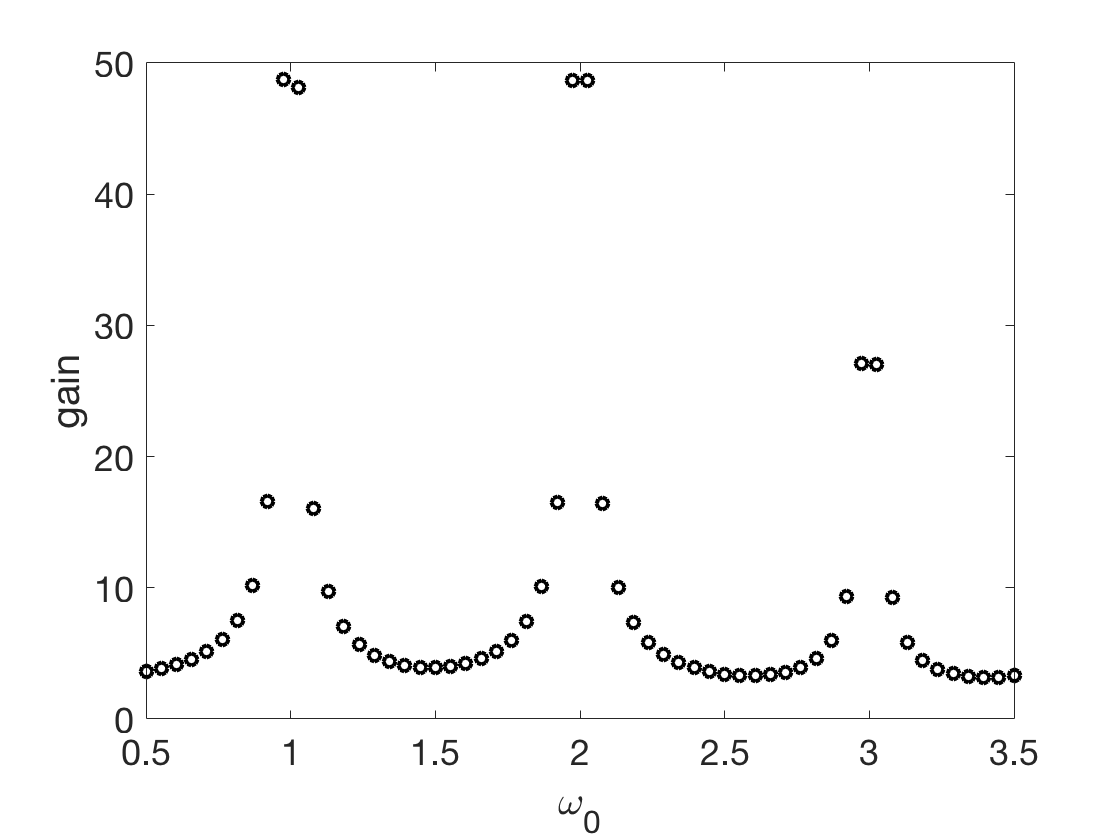

clf
L = chebop([0,pi]);
L.lbc = -3;  L.rbc = 1;
for omega0 = linspace(.5,3.5,58)
    L.op = @(u) diff(u,2) + omega0^2*u;
    G = max( abs(L\1) );
    plot(omega0,G,'ko')
    hold on
end
xlabel('\omega_0'), ylabel('gain')

## Matrix analogy

The structure of $u''+\omega_0^2 \;u$ is not unlike that of $Av-\lambda v$ in the eigenvalue problem...

A = [1 2 1; 0 2 5; 0 0 4]

A =      1     2     1
     0     2     5
     0     0     4


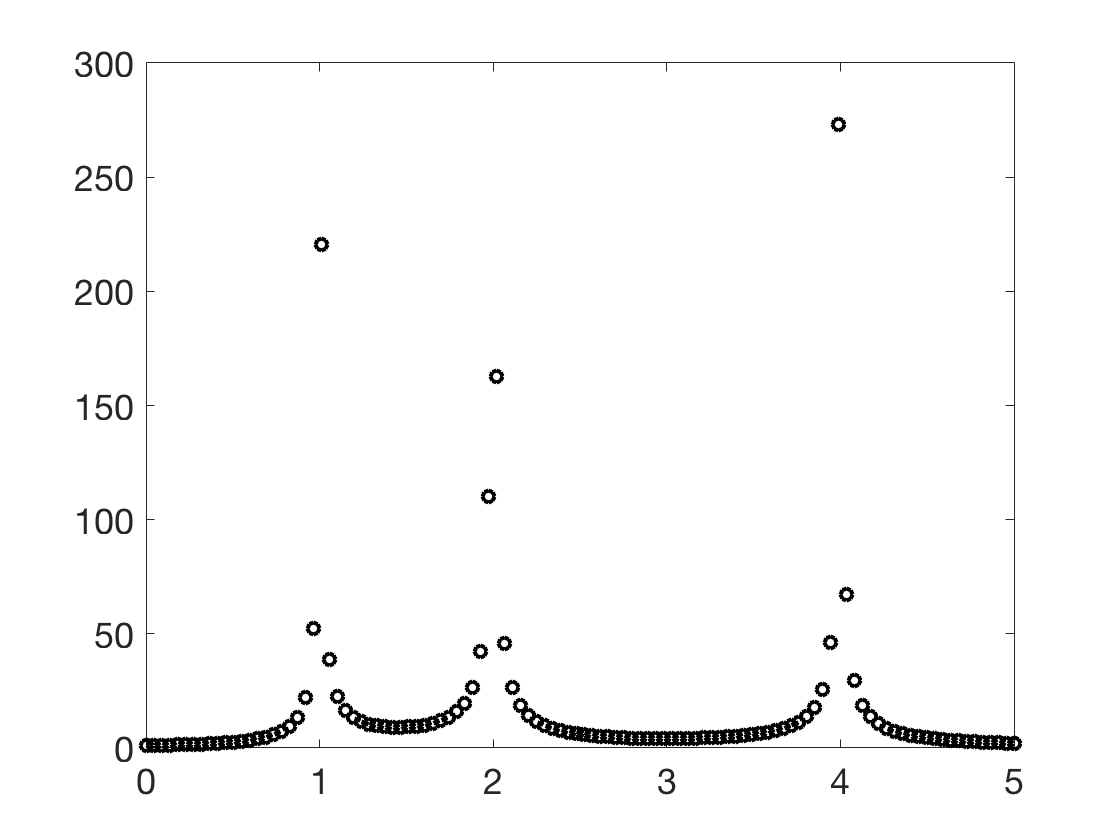

b = [1;1;1];

clf
for lambda = linspace(0,5,110)
    T = A - lambda*eye(3);
    G = max(abs(T\b));
    plot(lambda,G,'ko'), hold on
end

Not surprisingly, we get large solutions of $(A-\lambda I)x=b$ when $\lambda$ is an eigenvalue of $A$.

eigenvalues_of_A = eig(A)

eigenvalues_of_A =      1
     2
     4


Similarly, for a linear differential operator $L$, we can talk about solving$L[u]=\lambda u$ for a scalar $\lambda$ and nonzero function $u$

L = chebop(@(u) diff(u,2),[0 pi],0,0);
[V,D] = eigs(-L,5,0);
eigenvalues_of_L = diag(D)

eigenvalues_of_L =     1.0000
    4.0000
    9.0000
   16.0000
   25.0000


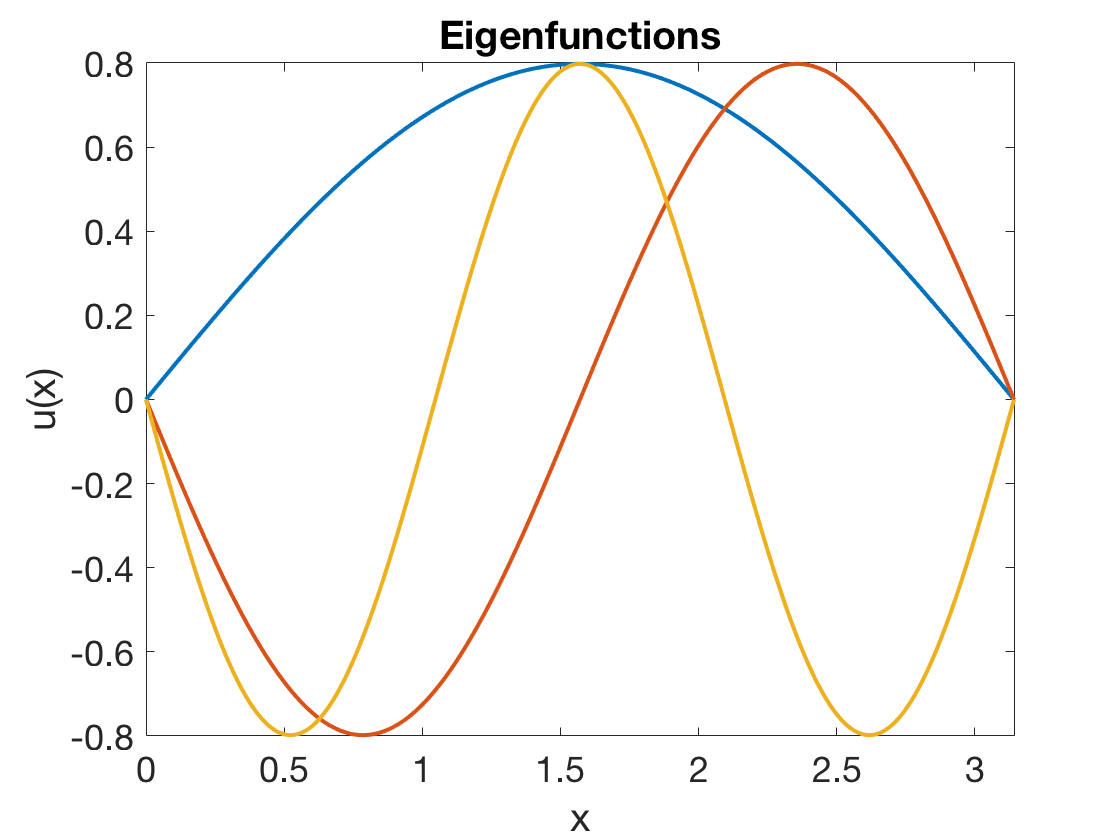

clf, plot(V(:,1:3))
xlabel x, ylabel u(x)
title('Eigenfunctions')

## Quantum leap

Eigenfunctions play a central role in quantum mechanics. One specifies a potential function, and the eigensolutions are the allowed energies/wave functions. Here's a case that can be solved analytically too.

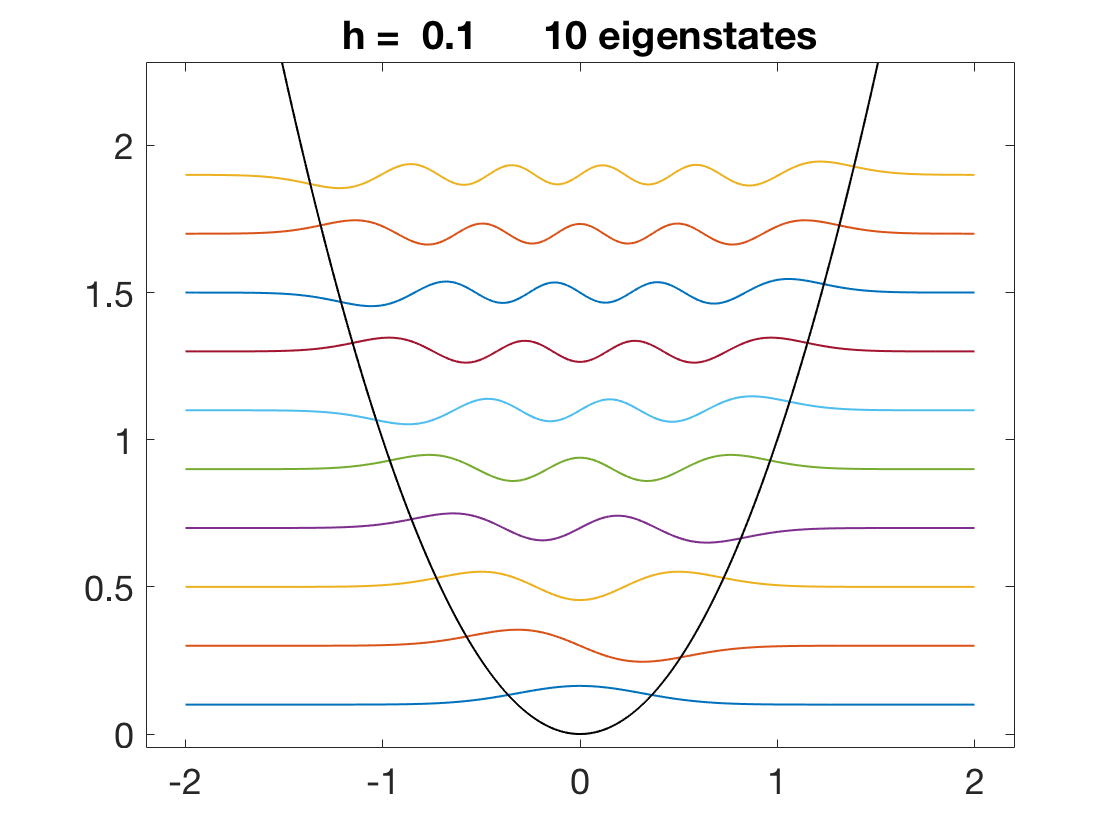

x = chebfun('x',[-2,2]);
quantumstates(x.^2);

This is a form of the double-well potential.

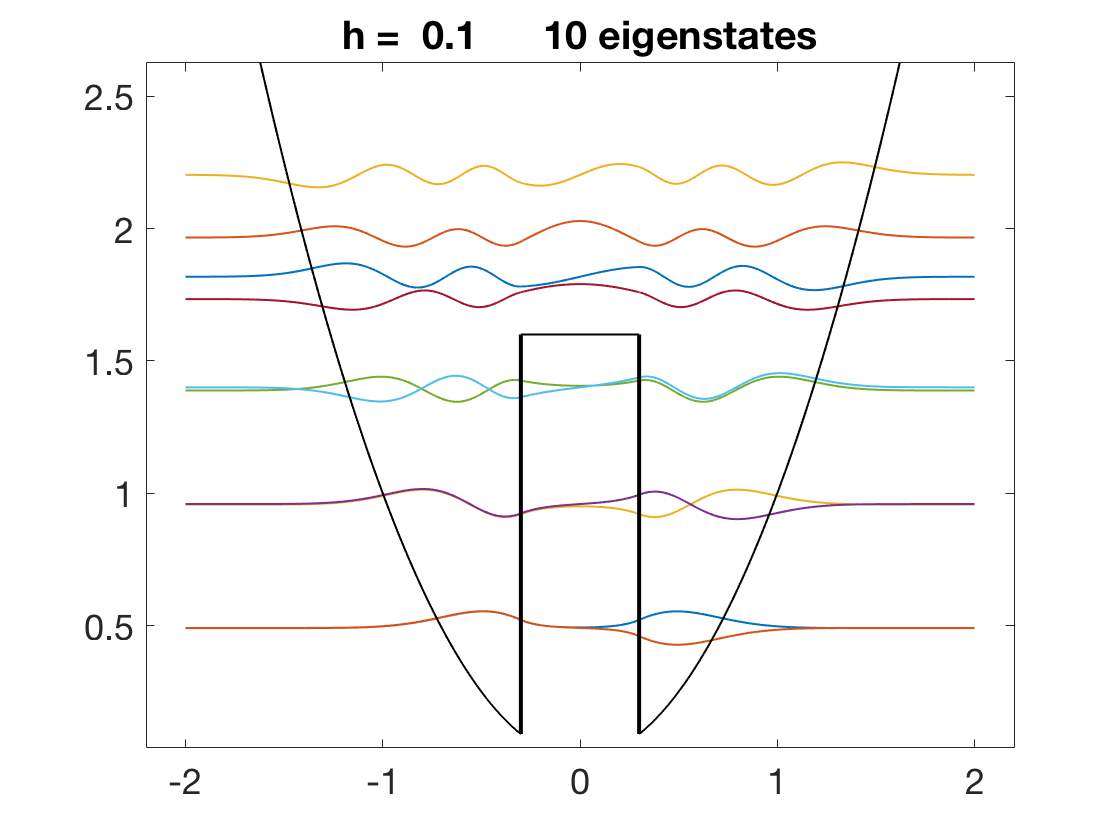

s = (abs(x)<=.3);
quantumstates(x^2*(1-s) + 1.6*s);